# **17 Stochastic models of outbreaks** 

**Overview**

**PART I: DTMC model**

Plot sample paths and (quasistationary) probability distribution in the following cases:

- DTMC SIS model 

- DTMC SIS model 

- DTMC SIR model 

- DTMC SIR model 

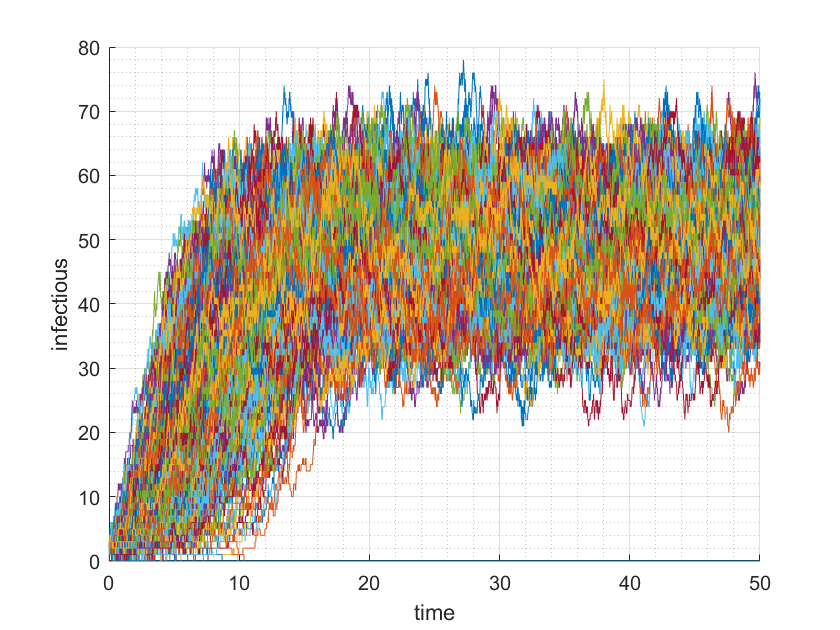

clc; clear; close all
%% Practice_SIS DTMC
%% part1 : #1
N = 100;
dt = 0.01;
beta = 1;
gamma = 0.25;
birth = 0.25;
I0 = 2;
S0 = N-I0;

t_start = 0;
t_end = 50;
tspan = t_start:dt:t_end;

simul_n = 500;


% transition matrix
b = @(i) (beta*i*(N-i)/N)*dt;
d = @(i) (birth+gamma)*i*dt;
s = @(i) 1-b(i)-d(i);

P = zeros(N+1,N+1);
P(1,1) = 1;

for i = 2:N+1
    P(i-1,i) = d(i-1);
    P(i,i) = s(i-1);
    P(i+1,i) = b(i-1);
  
end
P(N+2,:) = [];
P(N+1,N+1) = 1-d(N);

%% simulation
simulation = zeros(simul_n,length(tspan));
simulation(:,1) = I0;
for j = 1:simul_n
%simualation 한 줄씩 완성하기
    for t = 2:length(tspan)
    %% setting a1,a2
        I = simulation(j,t-1);
        if I == 0
            a_1 = 1;
            a_2 = 1;             
        elseif I == N
            a_1 = P(I+1,I+1); 
            a_2 = 1;
        elseif I~=0 && I~=N
            a_1 = P(I+1,I+1);
            a_2 = a_1+P(I,I+1);           
        end
        %%%%%%0--(I->I)--a1--(I->S)--a2--(S->I)--1%%%%%%
    %% random value가 (I->I),(I->S),(S->I)중에 어디 속하는지 정하고 next time step
    rv = rand;
        if(rv<=a_1)      
            simulation(j,t)=simulation(j,t-1); %(I->I)
        elseif(rv>a_1 && rv<=a_2)
            simulation(j,t)=simulation(j,t-1)-1; %(I->S)
        elseif(rv>a_2 && rv<=1)
            simulation(j,t)=simulation(j,t-1)+1; %(S->I)
        end
    end
end




figure(1)
hold on
for j = 1:simul_n
plot(tspan,simulation(j,:))
end
xlabel('time')
ylabel('infectious')
grid on; grid minor;
hold off